# Ecuaciones Diferenciales Parciales

Del conjunto de funciones que representan a las ecuaciones diferenciales ordinarias, existe un subconjunto de paricular de ecuaciones diferenciales parciales de segundo orden cuya forma es:

    
$$A\frac{\partial^2u}{\partial x^2}+B\frac{\partial^2u}{\partial x\partial y}+C\frac{\partial^2u}{\partial y^2}+D\frac{\partial u}{\partial x}+E\frac{\partial u}{\partial y}+Fu=G$$


    donde $A,B,C,D,E,G$ son funciones de $x$ y $y$. Es posible clasificar estas ecuaciones como:

    
$$\begin{array}{lr}
hiperbólicas & B^2-4AC>0\\
parabólicas &  B^2-4AC=0\\
elípticas &  B^2-4AC<0\\
\end{array}$$


Las ecuaciones **hiperbólicas** se utilizan normalmente cuando se presentan fenómenos de **propagación de ondas**, como luz o sonido. Las **parabolicas** se utilian para describir fenómenos de **difusión y transporte** como calor o concentración. Las **elípticas** se pueden encontrar aplicadas a estudiar **estados de equilibrio** como en el caso de potencailes electroestáticos o distribución de temperaturas en estados estacionarios.

## ______________________________________________

## Ecuación de Calor

    La ecuación de transmisión de calor en una dimensión se escrita como 

    
$$c\frac{\partial^2u}{\partial x^2}+\frac{\partial u}{\partial t}$$


    con condiciones a la frontera $u(0,t)=u_1$ y $u(a,t)=u_2$ para $t>0$  y una condición inicial $u(x,0)=f(x)$ con $0<x<a$.

###     Método explicito de diferencias finitas

    Es posible discretizarla por medio de la aproximación por diferencias finitas centradas como

    
$$\frac{\partial^2u}{\partial x^2}\approx \frac{1}{h^2}[u(x+h,t)-2u(x,t)+u(x-h,t)]$$


    y la aproximación por diferencias finitas hacia adelante:

    
$$\frac{\partial u}{\partial t}\approx \frac{1}{k}[u(x,t+k)-u(x,t)]$$


    obteniendo una expresión para la función evaluada en una posición $i+1$ y un tiempo $j+1$ como

    
$$u_{i}^{j+1}=\lambda u_{i+1}^{j}+(1-2\lambda)u_i^j+\lambda u_{i-1}^{j}$$


     donde $\lambda=ck/h^2$.

    La representación de esta ecuación está en un espacio que depende de $x$, la variables espacial, y $t$ la variable temporal y cuya solución está limitada por las condiciones a la frontera e iniciales. En el caso de la variable espacial, $x$ solo puede solucionarse entre los valores $x=0$ y los valores $x=a$; mientras que para la variable temporal las soluciones estana cotadas para cualquier tiempo $t\geq0$ como se muestra en la figura.

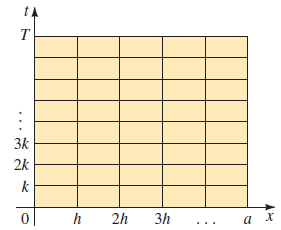

Para poder solucionar numericamente esta ecuación se utilizan los valores de las diferencias finitas centradas en $i-1,\,i$ e $i+1$ para algun $j$ con el objetivo de calcular la solución en $j+1$ para cualquier $i$. Un esquema representativo de este procedimiento se muestra en la figura

    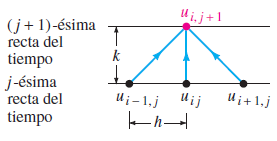

#### Ejemplo:

Considera el problema con valores a la frontera:


$$\begin{array}{lll} \frac{\partial^2u}{\partial x^2}=\frac{\partial u}{\partial t}, & 0<x<1,&\;0<t<0.5\\
u(0,t)=0,& u(1,t), &0\leq t\leq 0.5\\
u(x,0)=\text{sen}\,\pi x,&0\leq x\leq1
\end{array}$$


En este caso $c=1$, $a=1$ y $T=0.5$. Supongamos $n=5$ y $m=50$ tal que $h=1/5$, $k=0.5/50$ y $\lambda=0.25$. Entonces $x_i=i\frac{1}{5}$ para $i=0,1,2,3,4,5$ y $t_j=j\frac{1}{100}$ para $j=0,1,2,...,50$. Graficar la solución.


% Parámetros del problema
c = 1;          % Coeficiente de la ecuación
a = 1;          % Longitud del dominio espacial
T = 0.5;        % Tiempo final

n = 5;          % Número de divisiones espaciales
m = 50;         % Número de divisiones temporales
h = a/n;        % Tamaño del paso espacial
k = T/m;        % Tamaño del paso temporal
lambda = c^2*k/h^2;  % Parámetro lambda

% % Verificación de la estabilidad
% if lambda > 0.5
%     warning('El esquema puede ser inestable. Considere reducir k o aumentar h.');
% end

% Creación de la malla
x = linspace(0, a, n+1);    % Puntos espaciales (0 a 1 con n+1 puntos)
t = linspace(0, T, m+1);    % Puntos temporales (0 a 0.5 con m+1 puntos)

% Inicialización de la solución
u = zeros(n+1, m+1);        % Matriz para almacenar la solución

% Condición inicial
u(:,1) = sin(pi*x);         % u(x,0) = sen(πx)

% Condiciones de frontera
u(1,:) = 0;                 % u(0,t) = 0
u(end,:) = 0;               % u(1,t) = 0

% Método de diferencias finitas explícito
for j = 1:m
    for i = 2:n
        u(i,j+1) = u(i,j) + lambda*(u(i+1,j) - 2*u(i,j) + u(i-1,j));
    end
end

% Gráfica de contorno (x vs t)
figure;
contourf(t, x, u, 5, 'LineColor', 'none');
colorbar;
xlabel('Tiempo t');
ylabel('Posición x');
title('Mapa de contorno: Distribución de temperatura u(x,t)');
colormap(jet);

% Gráfica de superficie 3D
figure;
surf(t, x, u, 'EdgeColor', 'none');
xlabel('Tiempo t');
ylabel('Posición x');
zlabel('Temperatura u(x,t)');
title('Solución numérica de la ecuación del calor');
colorbar;
view(30, 45);
colormap(jet);

% Gráfica de evolución temporal
figure;
hold on;
plot(x, u(:,1), 'b-', 'LineWidth', 2, 'DisplayName', 't=0');
plot(x, u(:,round(m/4)), 'r-', 'LineWidth', 2, 'DisplayName', ['t=' num2str(t(round(m/4)))]);
plot(x, u(:,round(m/2)), 'g-', 'LineWidth', 2, 'DisplayName', ['t=' num2str(t(round(m/2)))]);
plot(x, u(:,end), 'k-', 'LineWidth', 2, 'DisplayName', ['t=' num2str(T)]);
xlabel('Posición x');
ylabel('Temperatura u(x,t)');
title('Evolución temporal de la solución');
legend('show');
grid on;
hold off;

### Método de Crank-Nicholson

Introducido por J. Crank y P. Nicholson en 1947, se usa más que nada para resolver la ecuación de calor. El algoritmo consiste en remplazar la segunda derivada parcial en $c\frac{\partial^2u}{\partial x^2}=\frac{\partial u}{\partial t}$ por un promedio de los cocientes en diferencias centrales, uno se evalúa en $t$ y el otro en $t+k$:


$$\frac{c}{2}\left[ \frac{u(x+h,t)-2u(x,t)+u(x-h,t)}{h^2}+\frac{u(x+h,t+k)-2u(x,t+k)+u(x-h,t+k)}{h^2} \right]=\frac{1}{k}[u(x,t+k)-u(x,t)]$$


donde de  nuevo $\lambda=ck/h^2$


$$-u_{i-1}^{j+1}+\alpha u_{i}^{j+1}-u_{i+1}^{j+1}=u_{i+1}^{j}-\beta u_i^j+u_{i-1}^j$$


donde $\alpha=2(1+1/\lambda)$ y $\beta=2(1-1/\lambda)$ para $j=0,1,...,m-1$ e $i=0,1,...,n-1$. Esquematicamente, se calcula un punto intermedio entre $j$ y $j+1$.

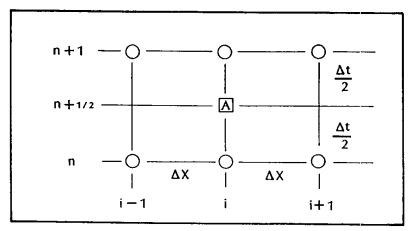

% Parámetros del problema
c = 1;          % Coeficiente de la ecuación
a = 1;          % Longitud del dominio espacial
T = 0.5;        % Tiempo final

n = 5;          % Número de divisiones espaciales
m = 50;         % Número de divisiones temporales
h = a/n;        % Tamaño del paso espacial
k = T/m;        % Tamaño del paso temporal
lambda = c^2*k/(2*h^2);  % Parámetro lambda para Crank-Nicholson

% Creación de la malla
x = linspace(0, a, n+1);    % Puntos espaciales
t = linspace(0, T, m+1);    % Puntos temporales

% Inicialización de la solución
u = zeros(n+1, m+1);        % Matriz para almacenar la solución

% Condición inicial
u(:,1) = sin(pi*x);         % u(x,0) = sen(πx)

% Condiciones de frontera
u(1,:) = 0;                 % u(0,t) = 0
u(end,:) = 0;               % u(1,t) = 0

% Construcción de las matrices del sistema
main_diag = (1 + 2*lambda)*ones(n-1,1);
off_diag = -lambda*ones(n-2,1);

A = diag(main_diag) + diag(off_diag,1) + diag(off_diag,-1);
B = diag((1 - 2*lambda)*ones(n-1,1)) + diag(lambda*ones(n-2,1),1) + diag(lambda*ones(n-2,1),-1);

% Resolución del sistema en cada paso de tiempo
for j = 1:m
    % Término independiente
    b = B*u(2:end-1,j);
    
    % Resolución del sistema lineal
    u(2:end-1,j+1) = A\b;
end

% Gráfica de contorno
figure;
contourf(t, x, u, 5, 'LineColor', 'none');
colorbar;
xlabel('Tiempo t');
ylabel('Posición x');
title('Crank-Nicholson: Mapa de contorno u(x,t)');
colormap(jet);

% Gráfica de superficie
figure;
surf(t, x, u, 'EdgeColor', 'none');
xlabel('Tiempo t');
ylabel('Posición x');
zlabel('Temperatura u(x,t)');
title('Solución con Crank-Nicholson');
colorbar;
view(30, 45);
colormap(jet);

% Gráfica de evolución temporal
figure;
hold on;
plot(x, u(:,1), 'b-', 'LineWidth', 2, 'DisplayName', 't=0');
plot(x, u(:,round(m/4)), 'r-', 'LineWidth', 2, 'DisplayName', ['t=' num2str(t(round(m/4)))]);
plot(x, u(:,round(m/2)), 'g-', 'LineWidth', 2, 'DisplayName', ['t=' num2str(t(round(m/2)))]);
plot(x, u(:,end), 'k-', 'LineWidth', 2, 'DisplayName', ['t=' num2str(T)]);
xlabel('Posición x');
ylabel('Temperatura u(x,t)');
title('Evolución temporal (Crank-Nicholson)');
legend('show', 'Location', 'northeast');
grid on;
hold off;

### `Ejercicio 1`

Resuleve el siguiente problema con valores a la frontera


$$\begin{array}{lll} \frac{\partial^2u}{\partial x^2}=\frac{\partial u}{\partial t}, & 0<x<2,&\;0<t<1\\
u(0,t)=0,& u(2,t)=0, &0\leq t\leq 1\\
u(x,0)=\left\{\begin{array}{l}1,\\0,\end{array}\right.&\begin{array}{l} 0\leq x\leq1\\1<x\leq 2\end{array}
\end{array}$$


usando $n=8$ y $m=40$

## _____________________________________________

## Ecuación de Onda

La ecuación que representa movimientos oscilatorios en una dimensión $u(x,t)$ como:


$$c^2\frac{\partial^2u}{\partial x^2}=\frac{\partial^2u}{\partial t^2}$$


Esta ecuación se puede discretizar con diferencias finitas por medio de:


$$\frac{\partial^2u}{\partial x^2}\approx \frac{1}{h^2}[u(x+h,t)-2u(x,t)+u(x-h,t)]$$



$$\frac{\partial^2u}{\partial t^2}\approx \frac{1}{k^2}[u(x,t+k)-2u(x,t)+u(x,t-k)]$$


y sustituyendo obtenemos el valor de la función en un tiempo posterior


$$u_{i}^{j+1}=\lambda^2\, u_{i+1}^{j}+2\,(1-\lambda^2)\,u_i^j+\lambda^2\, u_{i-1}^{j}-u_i^{j-1}\qquad(1)$$


para $i=1,2,...,n-1$ y $j=1,2,...,m-1$. Una forma de ver el cálculo en la malla es la siguiente:

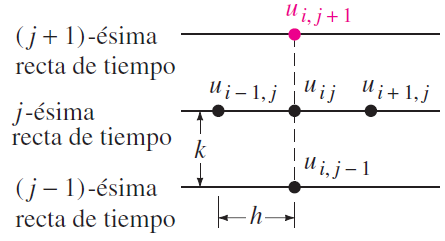

y donde las condiciones a la frontera $u_0^j=u(0,t_j)=0$ y $u_n^j=u(a,t_j)=0$ y la condición inicial $u_i^0=u(x_i,0)=f(x_i)$. Estas condiciones no determinan el valor de la función en $u_i^{j=1}$, el valor que esta "enmedio". Para resolver este problema usamos la discretización de la función de la condicion inicial para la velocidad $\frac{\partial u}{\partial t}=g(x)$ como:


$$g(x_i)=\frac{\partial u(x_i,0)}{\partial t}\approx\frac{u(x_i,t_{j+1})-u(x_i,t_{j-1})}{2k}\qquad(2)$$


es decir, la función de$g(x_i)$ alrededor del tiempo $t=0$ (en $t_j$). Esto supone que podemos calcular la función para un tiempo $t=-1$(en $t_{j-1}$), es decir, hacia el pasado.

Despejando esta la ecuación (2) en el caso **de la condición inicial (en **$t=0$**):**


$$u_i^{-1}=u_i^1-2kf(x_i)$$


y sustituyendo en la ecuación (1):


$$u_{i}^{1}=\frac{\lambda^2}{2}\, (u_{i+1}^{0}+u_{i-1}^0)+(1-\lambda^2)\, u_{i}^{0}+k\,g(x_i)\qquad(3)$$


#### Ejemplo

Aproximar la solución del problema con valores a la frontera


$$\begin{array}{lll} 4\frac{\partial^2u}{\partial x^2}=\frac{\partial^2 u}{\partial t^2}, & 0<x<1,&\;0<t<1\\
u(0,t)=0,& u(1,t)=0, &0\leq t\leq 1\\
u(x,0)=\text{sen}\,\pi x,&\frac{\partial u}{\partial t}\left|_{t=0}\right.=0&0\leq x\leq1
\end{array}$$


con $n=5$ y $m=20$. Donde $c=2$, $a=1$ y $T=1$. Por lo que $h=1/5$, $h=1/20$ y $\lambda=0.5$.

Para ello hay que identificar los valores $u_i^1$de la ecuación (3) para poder aplicar la ecuación (1)


$$u_i^1=\frac{0.5^2}{2}(u_{i+1}^0+u_{i-1}^0)+(1-0.5^2)u_i^0+0.05\cdot0$$


donde la ecuación $f(x=0)=\text{sen}\,\pi x|_{x=0}=0$. Entonces la ecuación para calcular las soluciones numericamente es:


$$u_i^{j+1}=0.25\,u_{i+1}^j+1.5\,u_i^j+0.25\,u_{i-1}^j-u_i^{j-1}$$


para $i=1,2,3,4$

% Programa para resolver la ecuación de onda 4u_xx = u_tt
% con condiciones de frontera e iniciales dadas

clear all;
close all;
clc;

% Parámetros del problema
c = 2;          % Velocidad de la onda
a = 1;          % Longitud del dominio espacial
T = 1;          % Tiempo final

n = 5;          % Número de puntos espaciales (x)
m = 20;         % Número de puntos temporales (t)

h = a/n;        % Paso espacial
k = T/m;        % Paso temporal
lambda = 0.5;   % Parámetro lambda = c*k/h

% Crear mallas
x = linspace(0, a, n+1);   % Puntos espaciales
t = linspace(0, T, m+1);   % Puntos temporales

% Inicializar matriz de solución u(x,t)
u = zeros(n+1, m+1);

% Condición inicial u(x,0) = sen(πx)
u(:,1) = sin(pi*x);

% Condición inicial de velocidad du/dt(x,0) = 0
% Usamos la aproximación para la primera fila temporal (j=1)
for i = 2:n
    u(i,2) = (lambda^2)/2 * (u(i+1,1) + u(i-1,1)) + (1 - lambda^2)*u(i,1) + k*0;
end

% Aplicar el esquema de diferencias finitas
for j = 2:m
    for i = 2:n
        u(i,j+1) = 0.25*u(i+1,j) + 1.5*u(i,j) + 0.25*u(i-1,j) - u(i,j-1);
    end
end

% Graficar la solución
[X, T] = meshgrid(x, t);
figure;
surf(X, T, u');
xlabel('Posición x');
ylabel('Tiempo t');
zlabel('Desplazamiento u(x,t)');
title('Solución numérica de la ecuación de onda 4u_{xx} = u_{tt}');
colorbar;
view(30, 45); % Ajustar ángulo de vista para mejor visualización

% Graficar perfil temporal para algunos puntos x
figure;
hold on;
for i = 1:2:n+1
    plot(t, u(i,:), 'LineWidth', 1.5, 'DisplayName', sprintf('x = %.2f', x(i)));
end
xlabel('Tiempo t');
ylabel('Desplazamiento u(x,t)');
title('Evolución temporal en diferentes posiciones');
legend('Location', 'best');
grid on;

% Graficar perfil espacial para algunos tiempos t
figure;
hold on;
for j = 1:5:m+1
    plot(x, u(:,j), 'LineWidth', 1.5, 'DisplayName', sprintf('t = %.2f', t(j)));
end
xlabel('Posición x');
ylabel('Desplazamiento u(x,t)');
title('Perfil espacial en diferentes tiempos');
legend('Location', 'best');
grid on;

### `Ejercicio 2`

Resuleve el prolema con valores a la frontera


$$\begin{array}{lll} c^2\frac{\partial^2u}{\partial x^2}=\frac{\partial^2 u}{\partial t^2}, & 0<x<a,&\;0<t<T\\
u(0,t)=0,& u(a,t)=0, &0\leq t\leq T\\
u(x,0)=f(x),&\frac{\partial u}{\partial t}\left|_{t=0}\right.=0&0\leq x\leq a
\end{array}$$


con $n=10$ y $m=25$, $c=\sqrt{2}$, $a=1$, $T=1$ y 


$$f(x)=\left\{\begin{array}{rr}
0,&0\leq x\leq 0.5\\
0.5&0.5< x\leq 1
\end{array}\right.$$


## _____________________________________________

## Ecuación de Laplace

La ecuación que representa movimientos oscilatorios en una dimensión $u(x,t)$ como:


$$\frac{\partial^2u}{\partial x^2}+\frac{\partial^2u}{\partial y^2}=0$$


Esta ecuación se puede discretizar con diferencias finitas por medio de:


$$\frac{\partial^2u}{\partial x^2}\approx \frac{1}{h^2}[u(x+h,y)-2u(x,y)+u(x-h,y)]$$



$$\frac{\partial^2u}{\partial y^2}\approx \frac{1}{h^2}[u(x,y+k)-2u(x,y)+u(x,y-k)]$$


En este caso tenemos una aproximación que depende d e 5 puntos.


$$\, u_{i+1}^{j}+u_i^{j+1}+u_{i-1}^{j}+u_i^{j-1}-4u_i^j=0 \qquad(4)$$


y visualizada como en la siguiente figura

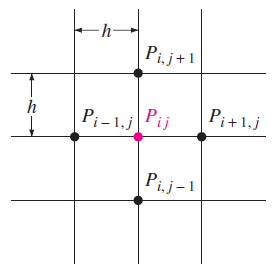

donde el punto que queremos calcular es el promedio de los puntos que lo rodean


$$u_i^j=\frac{1}{4}\left[  u_{i+1}^{j}+u_i^{j+1}+u_{i-1}^{j}+u_i^{j-1} \right]$$


Esto se presenta como un problema si pensamos en como se solucionaron las ecuaciones de calor y de onda. Sin embargo para este tipo de ecuaciones se presenta el **problema de Dirichlet **para la ecuación de Laplace $\nabla^2u=0$ que establece valores conocido para $u(x,y)$ en la frontera de la región $R$ donde se define el problema. Una visulaización sería como en la siguiente imagen.

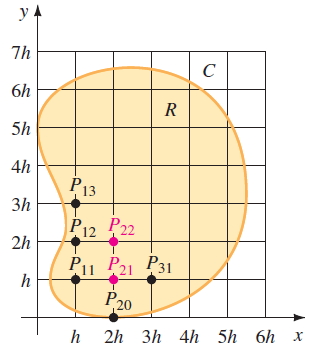

La ecuación (4) resulta entonces en un sistema de ecuaciones algebráicas cuyo tamaño depende de la cantidad de puntos son resolver dentro de la malla y diferentes a las condiciones a la frontera, es decir, todos los puntos rosas de la imagen anterior.

#### Ejemplo

Aproximar la solución del problema con valores a la frontera


$$\begin{array}{lll} \frac{\partial^2u}{\partial x^2}+\frac{\partial^2 u}{\partial y^2}=0, & 0<x<2,&\;0<t<2\\
u(0,y)=0,& u(2,y)=y(2-y), &0\leq y\leq 2\\
u(x,0)=0,&u(x,2)=\left\{\begin{array}{l}x,\\2-x\end{array}&\begin{array}{l}0\leq x\leq1\\1\leq x<2\end{array}
\end{array}$$


con un tamaño de paso $h=2/3$ por lo que existen 3 puntos ademas del cero en cada uno de los ejes. Al calcular las condiciones a la frontera en el problema de Dirichlet obtenemos valores para los puntos en el controno de la región

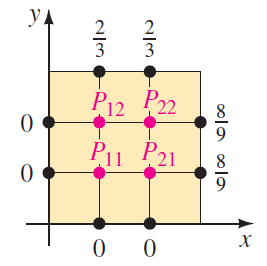

Tenemos que resolver el sistema de ecuaciones generado por la ecuación (4) para 4 de los 12 puntos, en donde los puntos $P_{ij}$ corresponden a las soluciones $u_i^j$ de la ecuación (4). EL sistema de ecuaciones entonces queda como:


$$\begin{array}{rcrcrcrl}
-4u_1^1&+&u_2^1&+&u_1^2& &&=0\\
u_1^1&-&4u_2^1&+& & &u_2^2&=-\frac{8}{9}\\
u_1^1& & &-&4u_1^2&+&u_2^2&=-\frac{2}{3}\\
 & &u_2^1&+&u_1^2&-&4u_2^2&=-\frac{14}{9}\\
\end{array}
$$


% Programa para resolver la ecuación de Laplace u_xx + u_yy = 0
% con condiciones de frontera mixtas

clear all;
close all;
clc;

% Parámetros del problema
a = 2;          % Longitud del dominio en x
b = 2;          % Longitud del dominio en y
h = 2/3;        % Tamaño de paso

% Crear malla
x = 0:h:a;      % Puntos en dirección x
y = 0:h:b;      % Puntos en dirección y
nx = length(x); % Número de puntos en x
ny = length(y); % Número de puntos en y

% Inicializar matriz de solución u(x,y)
u = zeros(nx, ny);

% Aplicar condiciones de frontera

% 1. u(0,y) = 0 (frontera izquierda)
u(1,:) = 0;

% 2. u(2,y) = y(2-y) (frontera derecha)
u(end,:) = y.*(2-y);

% 3. u(x,0) = 0 (frontera inferior)
u(:,1) = 0;

% 4. u(x,2) = función por partes (frontera superior)
for i = 1:nx
    if x(i) <= 1
        u(i,end) = x(i);
    else
        u(i,end) = 2 - x(i);
    end
end


% Resolver el sistema usando el método de diferencias finitas
% Para la ecuación de Laplace, usamos el esquema de 5 puntos:
% u(i,j) = (u(i+1,j) + u(i-1,j) + u(i,j+1) + u(i,j-1))/4

% max_iter = 4;    % Número máximo de iteraciones
% tol = 1e-4;         % Tolerancia para convergencia

% for iter = 1:max_iter
%     u_old = u;
    
    % Actualizar puntos interiores
    for i = 2:nx-1
        for j = 2:ny-1
            u(i,j) = (u(i+1,j) + u(i-1,j) + u(i,j+1) + u(i,j-1))/4;
        end
    end
    
    % % Verificar convergencia
    % if max(abs(u(:) - u_old(:))) < tol
    %     fprintf('Convergencia alcanzada en %d iteraciones.\n', iter);
    %     break;
    % end
% end

% Graficar la solución
[X, Y] = meshgrid(x, y);
figure;
surf(X, Y, u');
xlabel('Posición x');
ylabel('Posición y');
zlabel('Solución u(x,y)');
title('Solución numérica de la ecuación de Laplace');
colorbar;
view(30, 45); % Ajustar ángulo de vista

% Graficar contornos
figure;
contourf(X, Y, u', 15);
xlabel('Posición x');
ylabel('Posición y');
title('Mapa de contornos de la solución');
colorbar;
axis equal;

% Mostrar valores numéricos
disp('Solución numérica:');
disp(u);

### `Ejercicio 3`

La ecuación de Poission se describe por


$$\frac{\partial^2u}{\partial x^2}+\frac{\partial^2u}{\partial y^2}=f(x,y)$$


y donde su discretización queda de la forma 


$$\, u_{i+1}^{j}+u_i^{j+1}+u_{i-1}^{j}+u_i^{j-1}-4u_i^j=h^2f(x,y)$$


Analiza la región dada en la siguiente figura donde el tamaño de la malla es de $h=1/8$ y la condición a la forntera (puntos negros) es $u=0$.

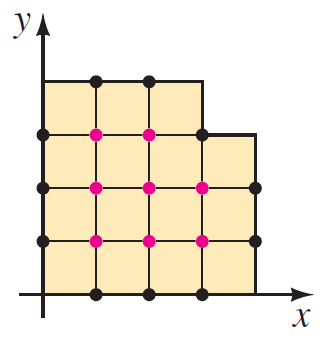

S